# Ordinære  differentialligninger

- TJEK DU HAR SKREVET LIGNINGERNE RIGTIGT FOR GUDS SKYLD

- Eulode 1 ligning

- Eulsys - flere ligninger koblede  (1. ordens)

- Runge-Kutte 4. ordens

- Under Eksamenssæt E20 er der med 3 ligninger til eulsys og rk4

## Eulode

clear

% Opgave 22.1a,

dydt = @(t,y) y.*t.^3 - 1.5.*y;

y0 = 1; h = 0.5; h2 = 0.25;

span = [0, 2];

[t,y,iter] = eulode(dydt,span,y0,h);
[t2,y2,iter2] = eulode(dydt,span,y0,h2);

dy_dt = dydt(t,y);
dy_dt2 = dydt(t2,y2);

disp(table(iter, t,y,dy_dt))

    iter     t        y          dy_dt  
    ____    ___    ________    _________

     0        0           1         -1.5
     1      0.5        0.25     -0.34375
     2        1    0.078125    -0.039062
     3      1.5    0.058594      0.10986
     4        2     0.11353      0.73792



disp(table(iter2, t2,y2,dy_dt2))

    iter2     t2       y2        dy_dt2  
    _____    ____    _______    _________

      0         0          1         -1.5
      1      0.25      0.625     -0.92773
      2       0.5    0.39307     -0.54047
      3      0.75    0.25795      -0.2781
      4         1    0.18842    -0.094212
      5      1.25    0.16487     0.074707
      6       1.5    0.18355      0.34415
      7      1.75    0.26959       1.0404
      8         2    0.52969        3.443



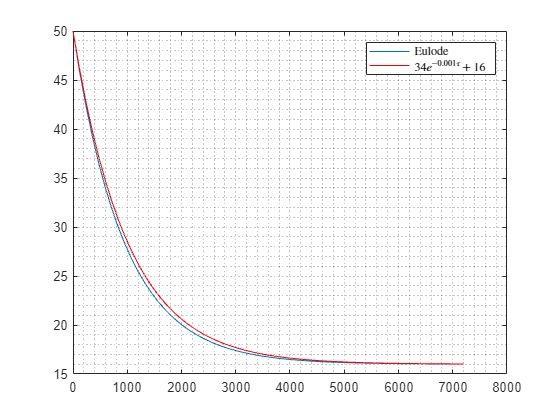

clear
% opgave 22.3


phi = 2508;
qm = 0.1;
tind = 10;  t0 = 50;
m = 100;
c = 4180;

tau_span = [0, 7200];

dtdtau = @(tau,t) (phi - qm*c*(t-tind))/(m*c);

[tau,t, iter] = eulode(dtdtau, tau_span,t0, 120);

%disp(table(iter, t, tau))

plot(tau, t), grid("minor")
hold on

t_ana = 34*exp(-0.001*tau)+16;

plot(tau, t_ana,'r')
legend('Eulode','$34e^{-0.001\tau} + 16$', "Interpreter", 'latex')
hold off

## Eulsys

% Givne værdier
clear

Pmidl=185; Pmax=214; Lmax=125; a=1.2; k=1.3; d=0.03; S0=24; B0=66;

t = [0, 5];
h = 0.25;

% Her er de 2 liginger koblet sammen. Rækkefølgen har betydning
dYdt = @(t, Y) [a*(Pmidl - Pmax + k*Y(2)), Lmax*exp(-d*Y(2)) - Y(1)]

dYdt = function_handle with value:
    @(t,Y)[a*(Pmidl-Pmax+k*Y(2)),Lmax*exp(-d*Y(2))-Y(1)]



[t, Y] = eulsys(dYdt,t, [S0, B0],h);

S = Y(:, 1);
B = Y(:, 2);

disp(table(t, S, B, 'VariableNames',{'t, uger', 'S, enheder/uge', 'B, enheder'}))

    t, uger    S, enheder/uge    B, enheder
    _______    ______________    __________

        0              24              66  
     0.25           41.04          64.315  
      0.5          57.423          58.593  
     0.75          71.574          49.626  
        1          82.228          38.784  
     1.25          88.654          27.989  
      1.5          90.869          19.321  
     1.75          89.704          14.107  
        2          86.506          12.148  
     2.25          82.544          12.227  
      2.5          78.612          13.246  
     2.75          75.078          14.595  
        3           72.07          15.995  
     3.25          69.608          17.317  
      3.5          67.662          18.503  
     3.75          66.178          19.526  
        4          65.093          20.377  
     4.25           64.34          21.061  
      4.5        


[maks, s] = max(S)

maks = 90.8693

s = 7


t(s)

ans = 1.5000

B(s)

ans = 19.3209

## Runge Kutta

Ligesom eulsys, men mere præcis gundet den højere orden

clear

Pmidl=185; Pmax=214; Lmax=125; a=1.2; k=1.3; d=0.03; S0=24; B0=66;

t = [0, 5];
h = 0.25;

dYdt = @(t, Y) [a*(Pmidl - Pmax + k*Y(2)), Lmax*exp(-d*Y(2)) - Y(1)]

dYdt = function_handle with value:
    @(t,Y)[a*(Pmidl-Pmax+k*Y(2)),Lmax*exp(-d*Y(2))-Y(1)]



[t,Y, iter] = rk4system(dYdt,t,[S0, B0],h);
iter

iter =      0
     1
     2
     3
     4
     5
     6
     7
     8
     9


S = Y(:, 1);
B = Y(:, 2);

disp(table(t, S, B, 'VariableNames',{'t, uger', 'S, enheder/uge', 'B, enheder'}))

    t, uger    S, enheder/uge    B, enheder
    _______    ______________    __________

        0              24              66  
     0.25           40.46          62.428  
      0.5          54.885          55.741  
     0.75          66.295          47.196  
        1          74.248          38.261  
     1.25          78.869            30.3  
      1.5          80.728          24.191  
     1.75           80.61          20.151  
        2          79.276          17.883  
     2.25          77.323          16.897  
      2.5           75.16          16.735  
     2.75          73.037          17.054  
        3          71.094          17.626  
     3.25          69.399          18.303  
      3.5          67.972          18.996  
     3.75          66.811          19.653  
        4          65.893          20.244  
     4.25           65.19          20.755  
      4.5        


[maks, s] = max(S)

maks = 80.7276

s = 7


t(s)

ans = 1.5000

B(s)

ans = 24.1915

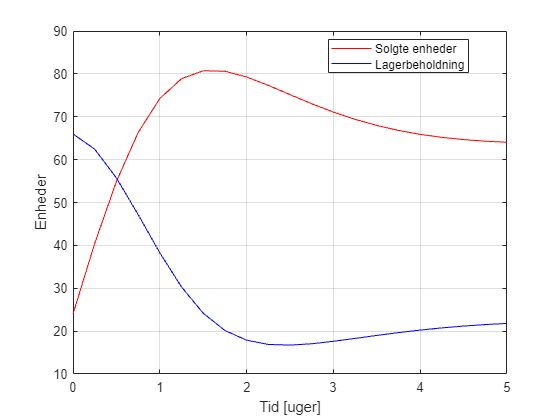


plot(t, S,'r', t, B, 'b'), grid("on"), xlabel("Tid [uger]"), ylabel("Enheder")
legend('Solgte enheder','Lagerbeholdning', 'Location','best')

# Funktioner

function [t,y,iter] = eulode(dydt,tspan,y0,h)
% eulode: Euler ODE solver
%   [t,y] = eulode(dydt,tspan,y0,h):
%           uses Euler's method to integrate an ODE
% input:
%   dydt = name of the M-file that evaluates the ODE
%   tspan = [ti, tf] where ti and tf = initial and
%   final values of independent variable
%   y0 = initial value of dependent variable
%   h = step size
% output:
%   t = vector of independent variable
%   y = vector of solution for dependent variable
if nargin<4,error('at least 4 input arguments required'),end
ti = tspan(1);tf = tspan(2);
if ~(tf>ti),error('upper limit must be greater than lower'),end
t = (ti:h:tf)'; n = length(t);
% if necessary, add an additional value of t
% so that range goes from t = ti to tf
if t(n)<tf
    t(n+1) = tf;
    n = n+1;
end
y = y0*ones(n,1); %preallocate y to improve efficiency
iter = [0,];
for i = 1:n-1 %implement Euler's method
    iter(end+1) = i;
    y(i+1) = y(i) + dydt(t(i),y(i))*(t(i+1)-t(i));
end
iter = iter';
end

function [t,Y] = eulsys(dYdt,tspan,Y0,h)
% eulsys: Euler solver for a system of ODEs
%   [t,Y] = eulsys(dYdt,tspan,Y0,h): uses Euler's
%     method to solve a system of first order 
%     differential equations.
% input:
%   dYdt = a function of (t,Y), where t is the independent
%     variable (scalar) and Y is a row vector of the 
%     dependent variables. The function should return a
%     row vector of derivatives of the independent
%     variables as given by the differential equations.
%   tspan = [ti, tf] where ti and tf = initial and
%     final values of independent variable
%   Y0 = initial value of dependent variables (row
%     vector)
%   h = step size
% output:
%   t = vector with values of the independent variable
%   Y = matrix with solution values of the dependent
%     variables. Each column represents one dependent 
%     variable
ti = tspan(1);
tf = tspan(2);
t = (ti:h:tf)';
n = length(t);
Y(1,:) = Y0;
for i = 1:n-1
  Y(i+1,:) = Y(i,:) + dYdt(t(i),Y(i,:))*h;
end
end



function [t,Y, iter] = rk4system(dYdt,tspan,Y0,h)
% rk4system: Fourth order Runge-Kutta solver for a system
%            of ODEs
%   [t,Y] = rk4system(dYdt,tspan,Y0,h): uses a fourth 
%     order Runge-Kutta method to solve a system of
%     first order differential equations.
% input:
%   dYdt = a function of (t,Y), where t is the independent
%     variable (scalar) and Y is a row vector of the 
%     dependent variables. The function should return a
%     row vector of derivatives of the independent
%     variables as given by the differential equations.
%   tspan = [ti, tf] where ti and tf = initial and
%     final values of independent variable
%   Y0 = initial value of dependent variables (row
%     vector)
%   h = step size
% output:
%   t = vector with values of the independent variable
%   Y = matrix with solution values of the dependent
%     variables. Each column represents one dependent 
%     variable
ti = tspan(1);
tf = tspan(2);
t = (ti:h:tf)';
n = length(t);
Y(1,:) = Y0;

iter = [0,];
for i = 1:n-1
    iter(end+1) = i;
  k1 = dYdt(t(i),Y(i,:));
  tmid1 = t(i) + h/2;
  Ymid1 = Y(i,:) + k1*h/2;
  k2 = dYdt(tmid1,Ymid1);
  tmid2 = t(i) + h/2;
  Ymid2 = Y(i,:) + k2*h/2;
  k3 = dYdt(tmid2,Ymid2);
  tend = t(i) + h;
  Yend = Y(i,:) + k3*h;
  k4 = dYdt(tend,Yend);
  phi = (k1 + 2*k2 + 2*k3 + k4)/6;
  Y(i+1,:) = Y(i,:) + phi*h;
end
iter = iter';
end